# 线性约束最小方差波束形成器(LCMV)

LCMV是MVDR波束形成器的直接推广,LCMV波束形成中，在某些线性约束条件下对总输出功率进行最小化，如下面问题所述：

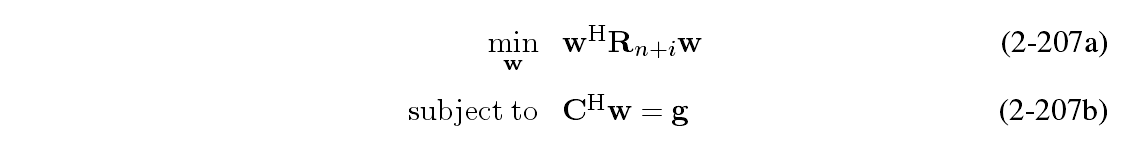

式中，C是(N+1)xNc约束矩阵，g是对应的约束响应矢量。

线性约束包括**点约束**，**导数约束**和**特征向量约束**等。

其中**导数约束**包括 主瓣展宽 和 零陷展宽两种。**特征向量约束**一般用于特征干扰相消器中。

假设期望信号为单位增益约束，其他约束为在固定方向形成零陷，则


$$C=[a(\theta_0),a(\theta_{C1}),...,a(\theta_{CN_c-1})],g=[1,0,...,0]^T$$


则LCMV最优权矢量为：


$$W_{LCMV}=R_X^-1C(C^HR_X^-1C)^-1g$$


%--------------------------------------------------------------------------
%   初始化
%--------------------------------------------------------------------------
clear;clc;

%--------------------------------------------------------------------------
%   参数设置
%--------------------------------------------------------------------------
N = 64;                                                                      %阵元个数
theta_tgt = 0;                                                            %信号
theta_jam = [9.5 10 10.5 29.5 30 30.5];

theta = [theta_tgt theta_jam];
angle_axis = -90:0.01:90;

%--------------------------------------------------------------------------
%   生成3个来向的导向矢量
%--------------------------------------------------------------------------
c = 3e8;                                                                    %光速
lambda = 1;                                                                 %波长
dd = lambda/2;                                                              %阵元间距d = lambda/2
d = 0:dd:(N-1)*dd;                                                          %构建阵列坐标
A = exp(1j.*2*pi*d.'*sind(theta));                                          %构建阵列流形


R_x = A(:,2:end)*A(:,2:end)';

%--------------------------------------------------------------------------
%   对角加载
%--------------------------------------------------------------------------
R_x = R_x + eye(size(R_x));

C = A;
%--------------------------------------------------------------------------
%   窗函数多波束约束
%--------------------------------------------------------------------------
C(:,1) = taylorwin(N).*C(:,1);

%--------------------------------------------------------------------------
%   功率控制
%--------------------------------------------------------------------------
g = zeros(length(theta),1);
g(1) = db2pow(0);
g(2) = db2pow(-inf);
g(3) = db2pow(-inf);
g

g =      1
     0
     0
     0
     0
     0
     0


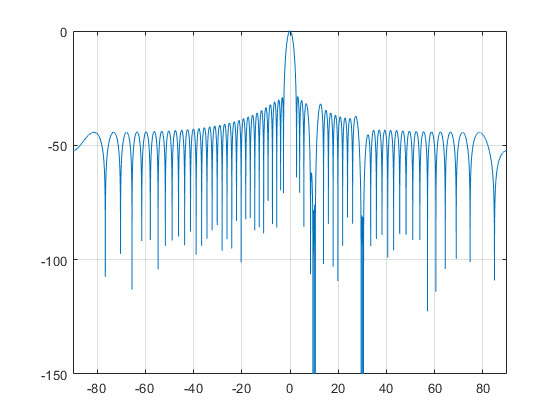

w_lcmv = R_x^-1*C*(C'*R_x^-1*C)^-1*g;

%--------------------------------------------------------------------------
%   绘制天线方向图
%--------------------------------------------------------------------------
[~,~,L_dB] = L_norm_array_pattern(w_lcmv,angle_axis);


figure(1)
plot(angle_axis,L_dB);grid on;axis([-90 90 -150 0])